Slike za uvodni del iskanja parametrizacije

export_images = false; % nastavi na false da se slike ne exportajo

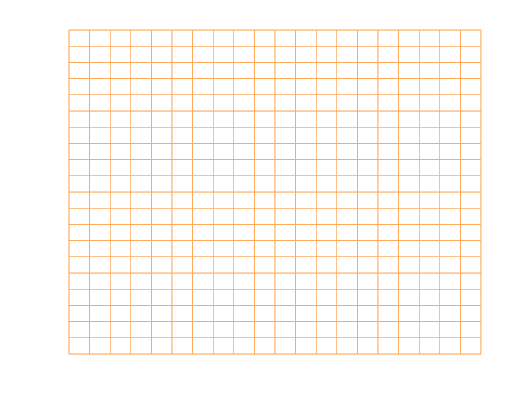

N = 5;
u = linspace(0, 1, 21);

Bx = repmat(1:N, N, 1);
By = Bx';
Bz = zeros(size(Bx));

[bx, by, bz] = bezier2(Bx, By, Bz, u, u);

figure
surf(bx, by, bz, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
grid off
set(gca,'visible','off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b4_param_domain.pdf', 'ContentType', 'vector')
end

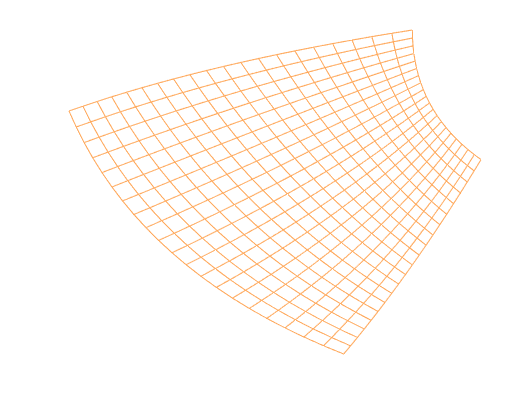

Bx = [1 -2 -3; 2 1 -1; 3 2 2];
By = [0 0.5 1.5; 0.5 1 1.8; 1.2 1.5 2];

Bz = zeros(size(Bx));

[bx, by, bz] = bezier2(Bx, By, Bz, u, u);

figure
surf(bx, by, bz, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
grid off
set(gca,'visible','off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b4_conformal.pdf', 'ContentType', 'vector')
end

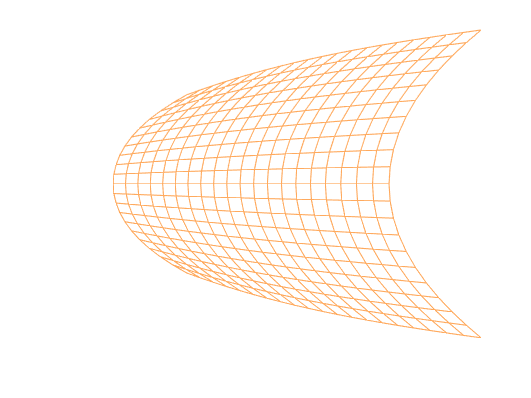

Bx = [4 7 10 14; 2 0 0 12; 1 0 0 10; 1 0 0 10; 2 0 0 12; 4 7 10 14];
By = [5 3 2 1; 7 0 0 4; 9 0 0 8; 12 0 0 13; 14 0 0 17; 16 18 19 20];

[bx, by] = coons_patch(Bx, By);
[bx, by, bz] = bezier2(bx, by, zeros(size(bx)), u, u);

figure
surf(bx, by, bz, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
grid off
set(gca,'visible','off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b4_isoparametric.pdf', 'ContentType', 'vector')
end